# 다변량선형회귀분석 

modelspec = ' cap ~ maxTimeDelta + maxTemp + ohm  ';

Re Rct 제거하고 테스트 

시계열 데이타이지만 각 피쳐와 Capacity는  시계열 모델이 아니라 일반적인 structural 모델이다.

load B0005.mat
load B0006.mat
load B0007.mat
load B0018.mat
BAT1 =B0005;
BAT2 =B0006;
BAT3 =B0007; 
BAT4 =B0018; 


## 피쳐 얻어오기

array2table 로 테이블을 만들때 선형회구를 하기 위해 종속변수를 제일 뒤에 두어라

[cap,maxTemp,maxTimeDelta,abnormal,ohm,re_c,re_d] = extract_feature_v1(BAT1);
%maxTimeDelta(abnormal) <= 이상값을 변경하는 것도 필요하다. 차후에.
dataVectorAll = [  maxTimeDelta' maxTemp' ohm'   cap'];
dataVector = [  maxTimeDelta' cap'];

[cap2,maxTemp2,maxTimeDelta2,abnormal2,ohm2,re_c2,re_d2] = extract_feature_v1(BAT2);
dataVectorAll2 = [maxTimeDelta2' maxTemp2' ohm2'  cap2'  ];
dataVector2 = [maxTimeDelta2' cap2'  ];

[cap3,maxTemp3,maxTimeDelta3,abnormal3,ohm3,re_c3,re_d3] = extract_feature_v1(BAT3);
dataVectorAll3 = [maxTimeDelta3' maxTemp3' ohm3'   cap3'  ];
dataVector3 = [maxTimeDelta3'  cap3'  ];

%{
% extract_feature function has errors on BAT4
[cap4,maxTemp4,maxTimeDelta4,abnormal4,ohm4,re_c4,re_d4] = extract_feature(BAT4);
dataVectorAll4 = [maxTimeDelta4' maxTemp4' ohm4'   cap4'  ];
dataVector4 = [maxTimeDelta4' cap4'  ];
%}

#### 백터를 테이블로 저장하기


tbl = array2table(dataVectorAll,...
    'VariableNames',{'maxTimeDelta','maxTemp','ohm','cap'});
    
% https://kr.mathworks.com/help/stats/fitlm.html
modelspec = ' cap ~ maxTimeDelta + maxTemp + ohm  ';
mdl = fitlm(tbl,modelspec )

mdl = Linear regression model:
    cap ~ 1 + maxTimeDelta + maxTemp + ohm

Estimated Coefficients:
                          Estimate                   SE                   tStat                 pValue       
                    ____________________    ____________________    _________________    ____________________

    (Intercept)          4.0958529260748       0.227155110205607     18.0310842330048    7.46164930980593e-41
    maxTimeDelta    0.000196894463615833    1.30246355211347e-05     15.1170804969044     5.8318591311248e-33
    maxTemp          -0.0952839654207921     0.00835224901979087    -11.4081806223706    1.35336543592271e-22
    ohm                -82.6228614134608        13.4185717416945    -6.15735139357142    5.43873148600241e-09


Number of observations: 169, Error

mdl.Coefficients

ans = 4×4 table
                          Estimate                   SE                   tStat                 pValue       
                    ____________________    ____________________    _________________    ____________________

    (Intercept)          4.0958529260748       0.227155110205607     18.0310842330048    7.46164930980593e-41
    maxTimeDelta    0.000196894463615833    1.30246355211347e-05     15.1170804969044     5.8318591311248e-33
    maxTemp          -0.0952839654207921     0.00835224901979087    -11.4081806223706    1.35336543592271e-22
    ohm                -82.6228614134608        13.4185717416945    -6.15735139357142    5.43873148600241e-09


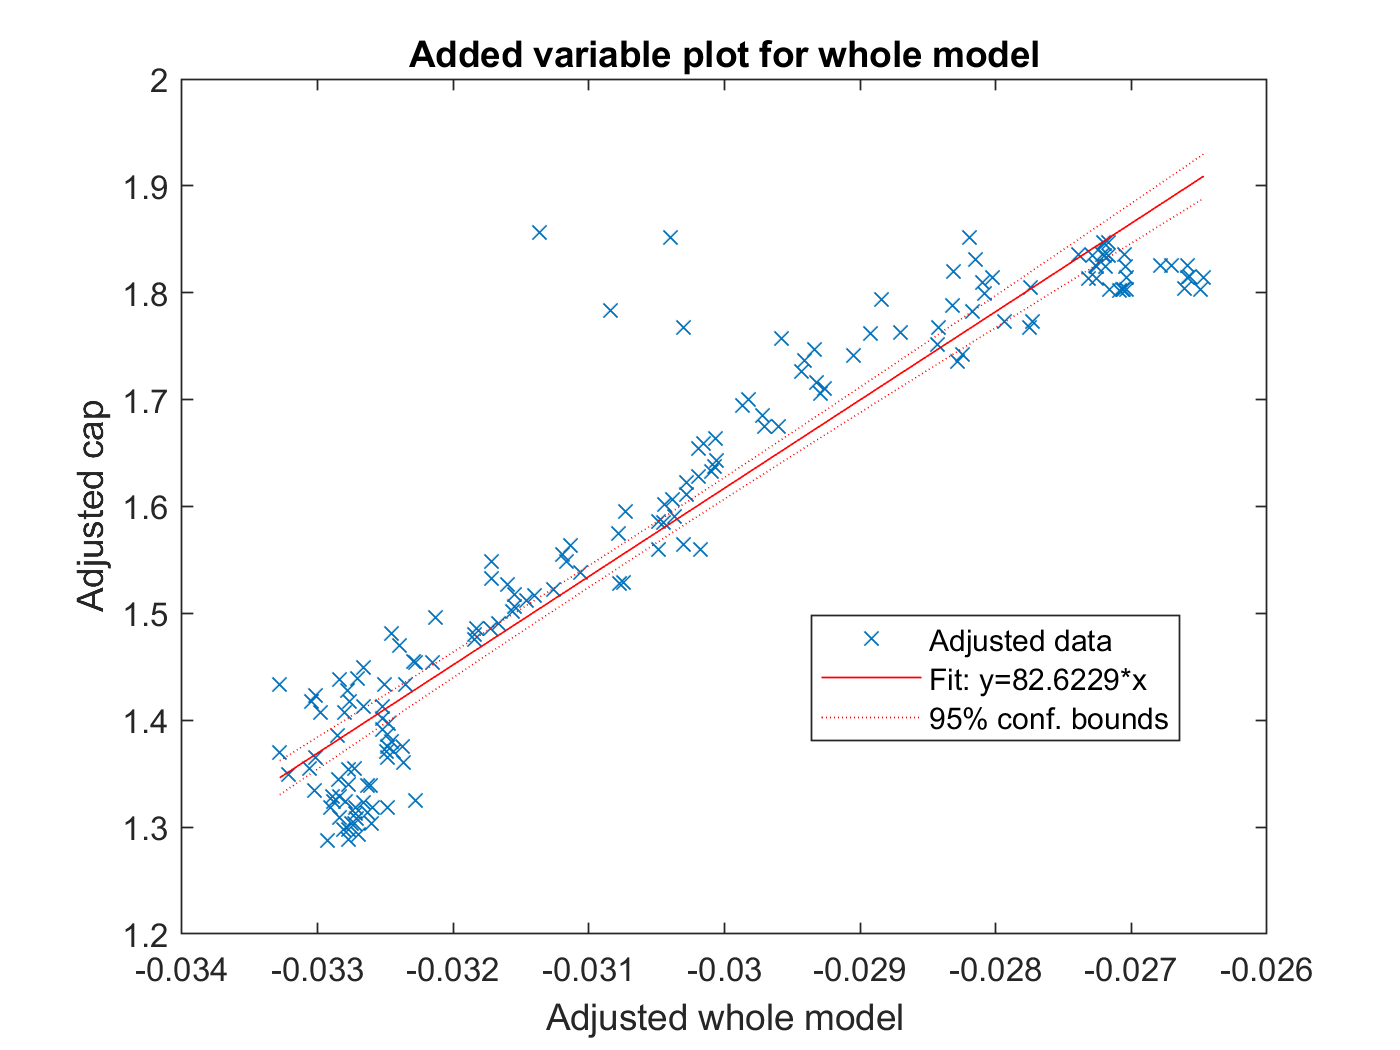

% https://kr.mathworks.com/help/stats/linearmodel.plot.html
plot(mdl)

모델링된 선형회구식을 가지고 원래 데이타와 예측한 데이타를 비교하자

차이가 많이 난다.

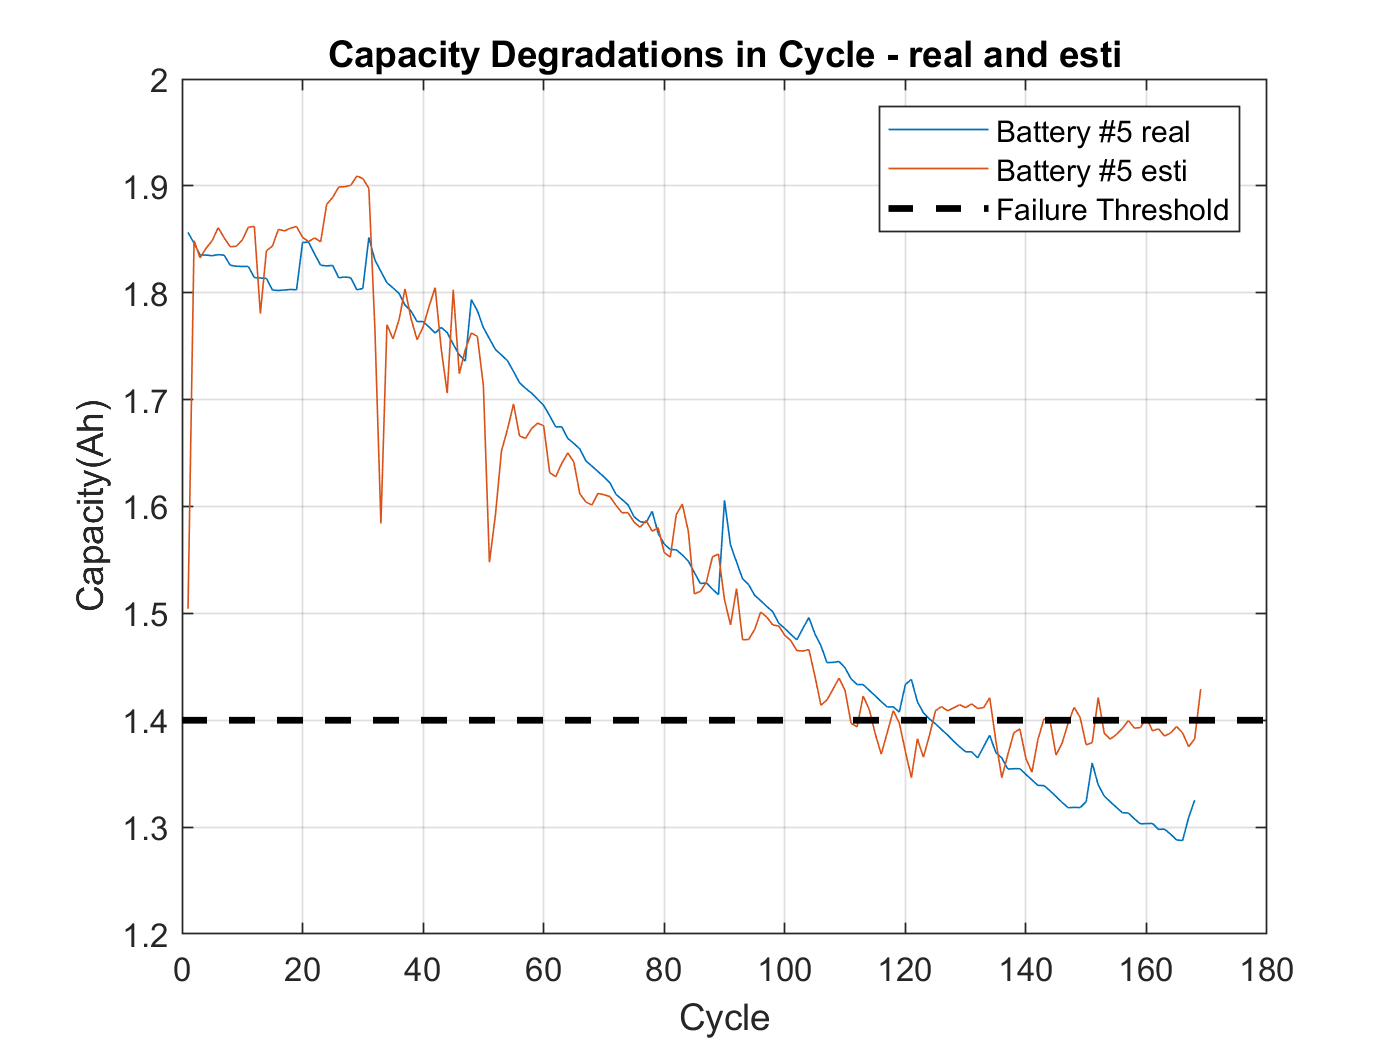

% 1 + maxTimeDelta + maxTemp + ohm + re_c + re_d
cap5hat = table2array(mdl.Coefficients(1,1)) ...
    + table2array(mdl.Coefficients(2,1))*maxTimeDelta ... 
    + table2array(mdl.Coefficients(3,1))*maxTemp ... 
    + table2array(mdl.Coefficients(4,1))*ohm ;


figure
plot(cap5), hold on, plot(cap5hat')
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 real', 'Battery #5 esti', 'Failure Threshold')
title('Capacity Degradations in Cycle - real and esti')

모델설정후 잔차에 대한 히스토그램을 그린다.

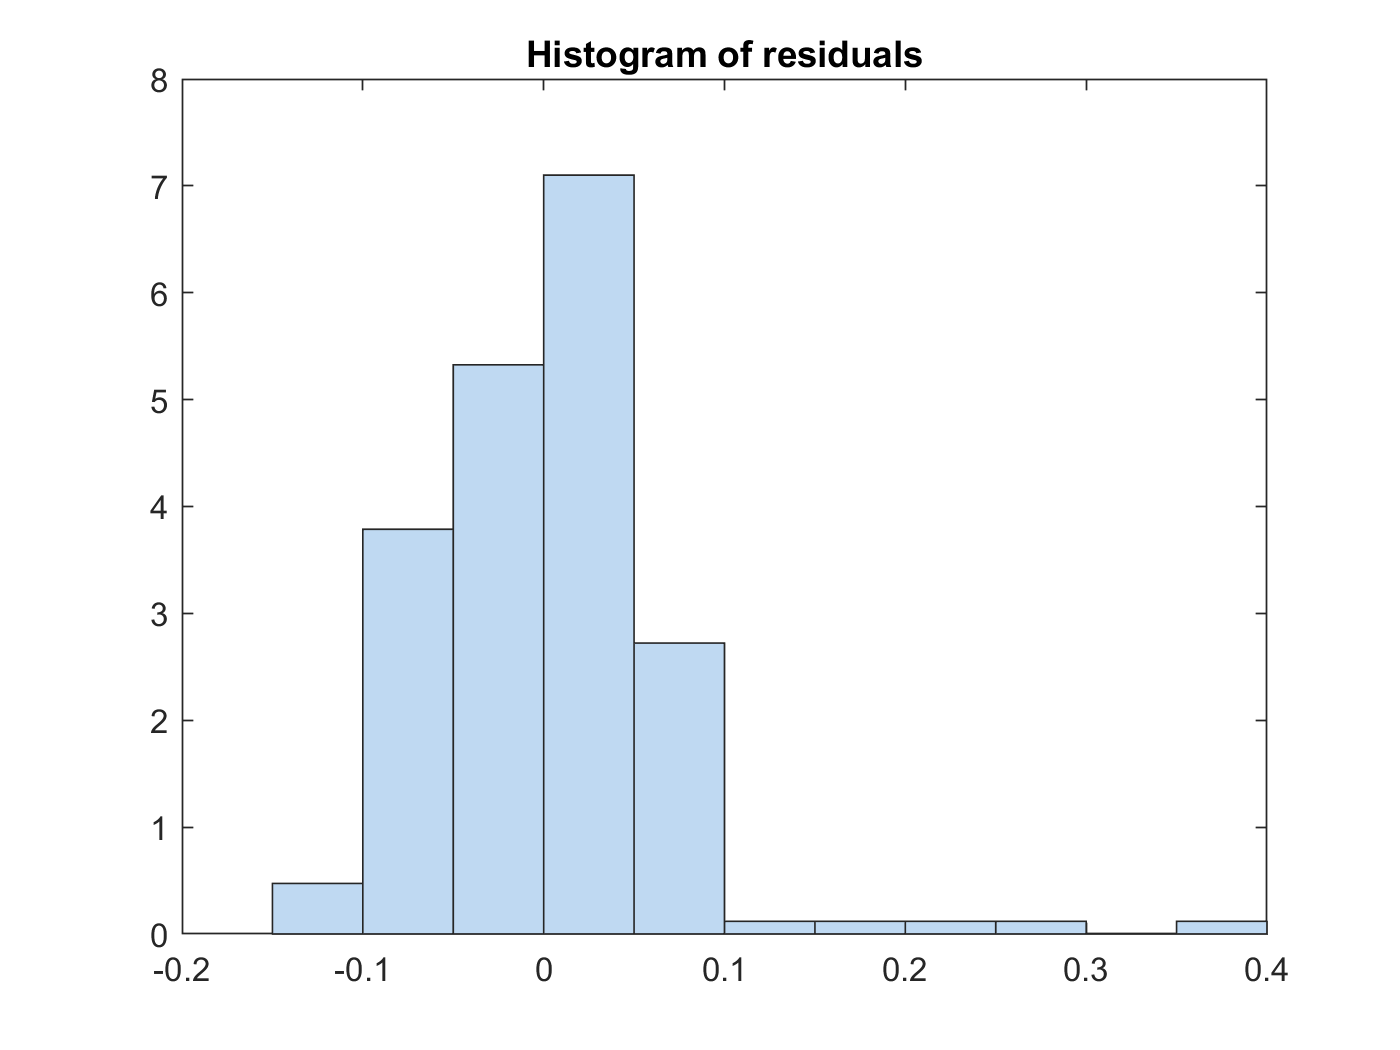

plotResiduals(mdl)

잔차 분포에서 outer를 제거하자

outlier = mdl.Residuals.Raw > 0.15 ;
find(outlier)

ans =      1
    33
    51
    52


모델에 사용된 데이타에서 outer 를 제외하고 모델링하라.

mdl = fitlm(tbl,modelspec,...
    'Exclude',find(outlier));

outer 정보 출력

mdl.ObservationInfo(find(outlier),:)

ans = 4×4 table
    Weights    Excluded    Missing    Subset
    _______    ________    _______    ______

       1        true        false     false 
       1        true        false     false 
       1        true        false     false 
       1        true        false     false 


outer를 제거 후 회귀선이 잘 그려지는지 확인하자.

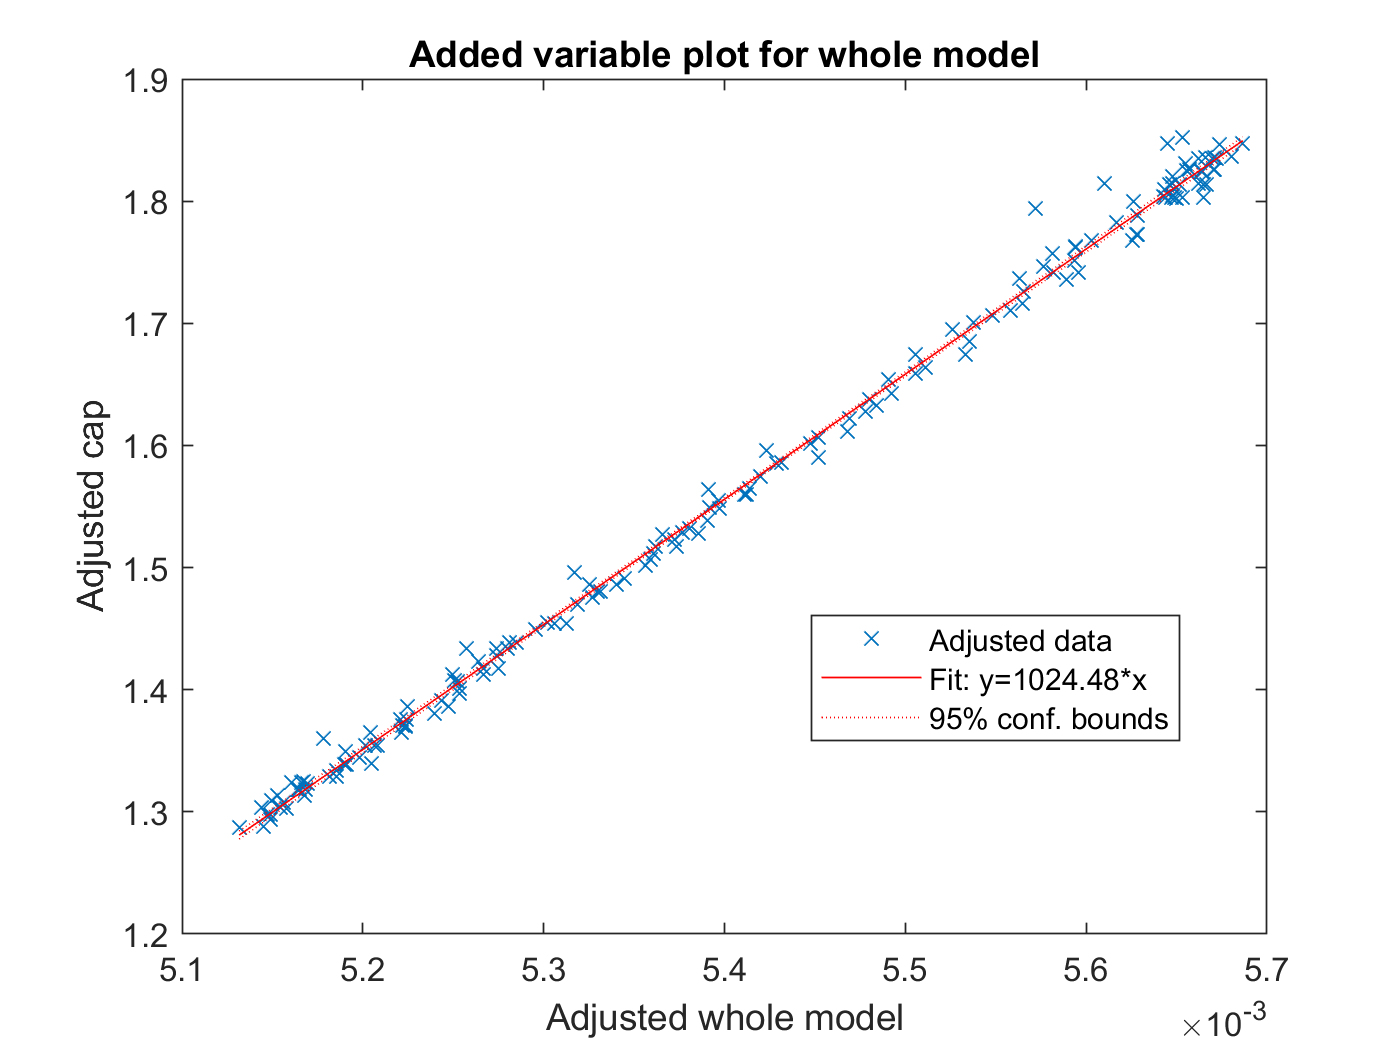

plot(mdl1)

모델링된 선형회구식을 가지고 원래 데이타와 예측한 데이타를 비교하자

차기가 많이 줄어들었다.

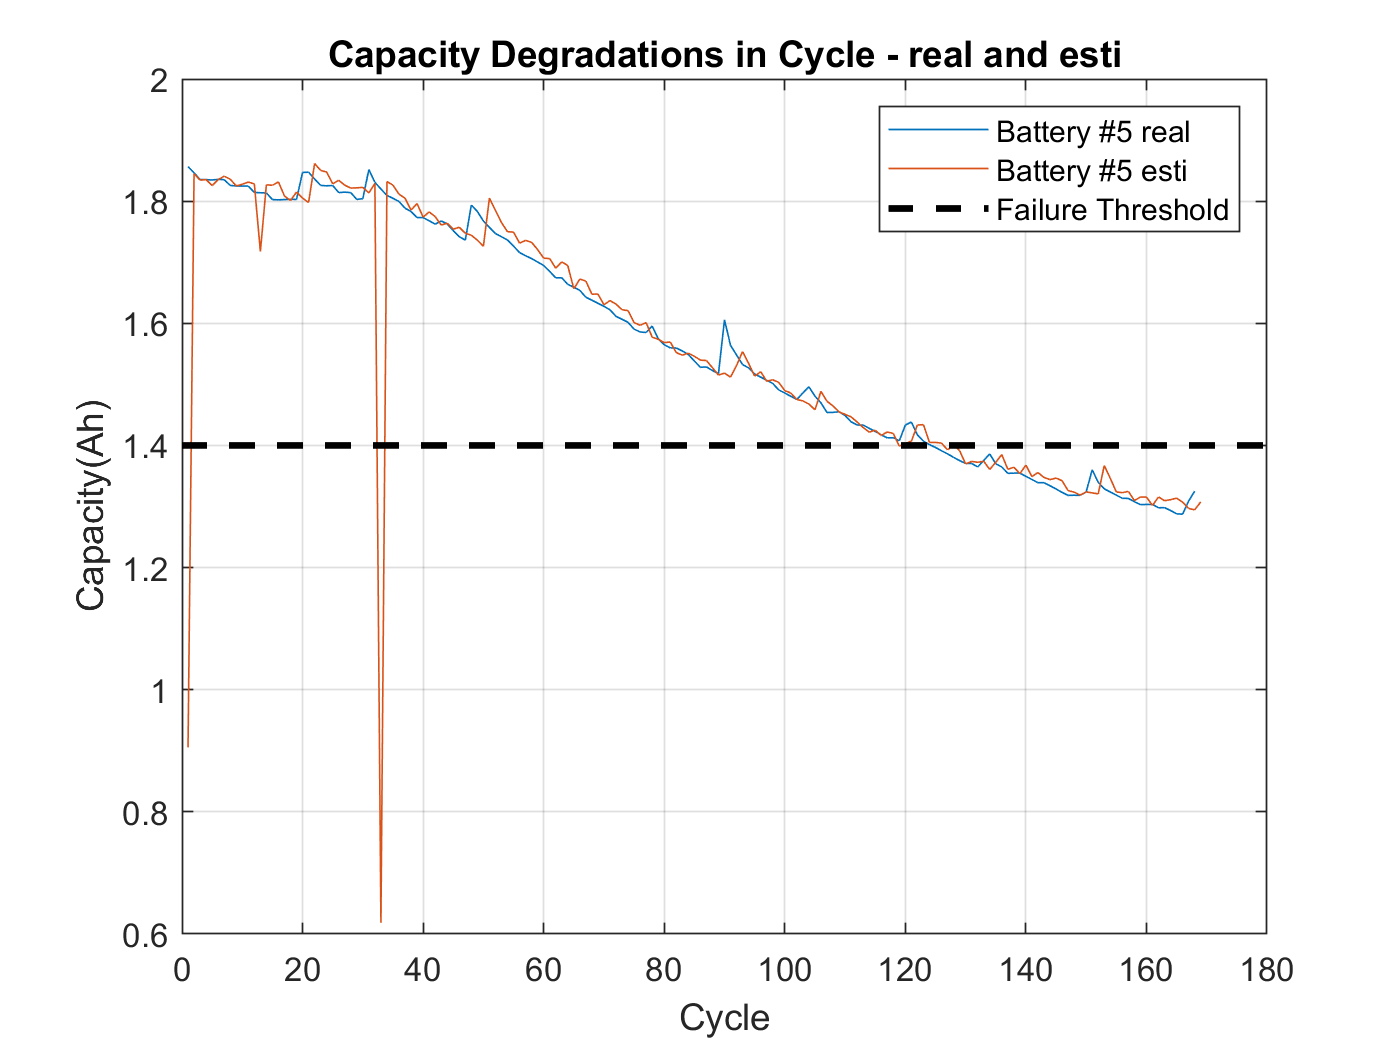

% 1 + maxTimeDelta + maxTemp + ohm + re_c + re_d
cap5hat = table2array(mdl.Coefficients(1,1)) ...
    + table2array(mdl.Coefficients(2,1))*maxTimeDelta ... 
    + table2array(mdl.Coefficients(3,1))*maxTemp ... 
    + table2array(mdl.Coefficients(4,1))*ohm ;

figure
plot(cap5), hold on, plot(cap5hat')
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 real', 'Battery #5 esti', 'Failure Threshold')
title('Capacity Degradations in Cycle - real and esti')

아래는 다변량 선형회귀에서 변수를 줄이기 위한 것이다.

mdl1 = step(mdl,'NSteps',10)

1. Adding maxTimeDelta:ohm, FStat = 78.4583, pValue = 1.48556e-15
2. Adding maxTemp:ohm, FStat = 13.9493, pValue = 0.000261288
3. Adding maxTimeDelta:maxTemp, FStat = 11.7499, pValue = 0.000775923


mdl1 = Linear regression model:
    cap ~ 1 + maxTimeDelta*maxTemp + maxTimeDelta*ohm + maxTemp*ohm

Estimated Coefficients:
                                  Estimate                    SE                   tStat                 pValue       
                            _____________________    ____________________    _________________    ____________________

    (Intercept)                  -3.9762807044696         1.2993968649399    -3.06009719721272     0.00260036824502209
    maxTimeDelta             0.000867641732666124    0.000233554528835474     3.71494287433547    0.000281520670722043
    maxTemp                     0.192580900054625         0.0448735910979     4.29163112072921    3.08160237147364e-05
    ohm                          1023.49004443597        255.595323126159  

plot(mdl1)

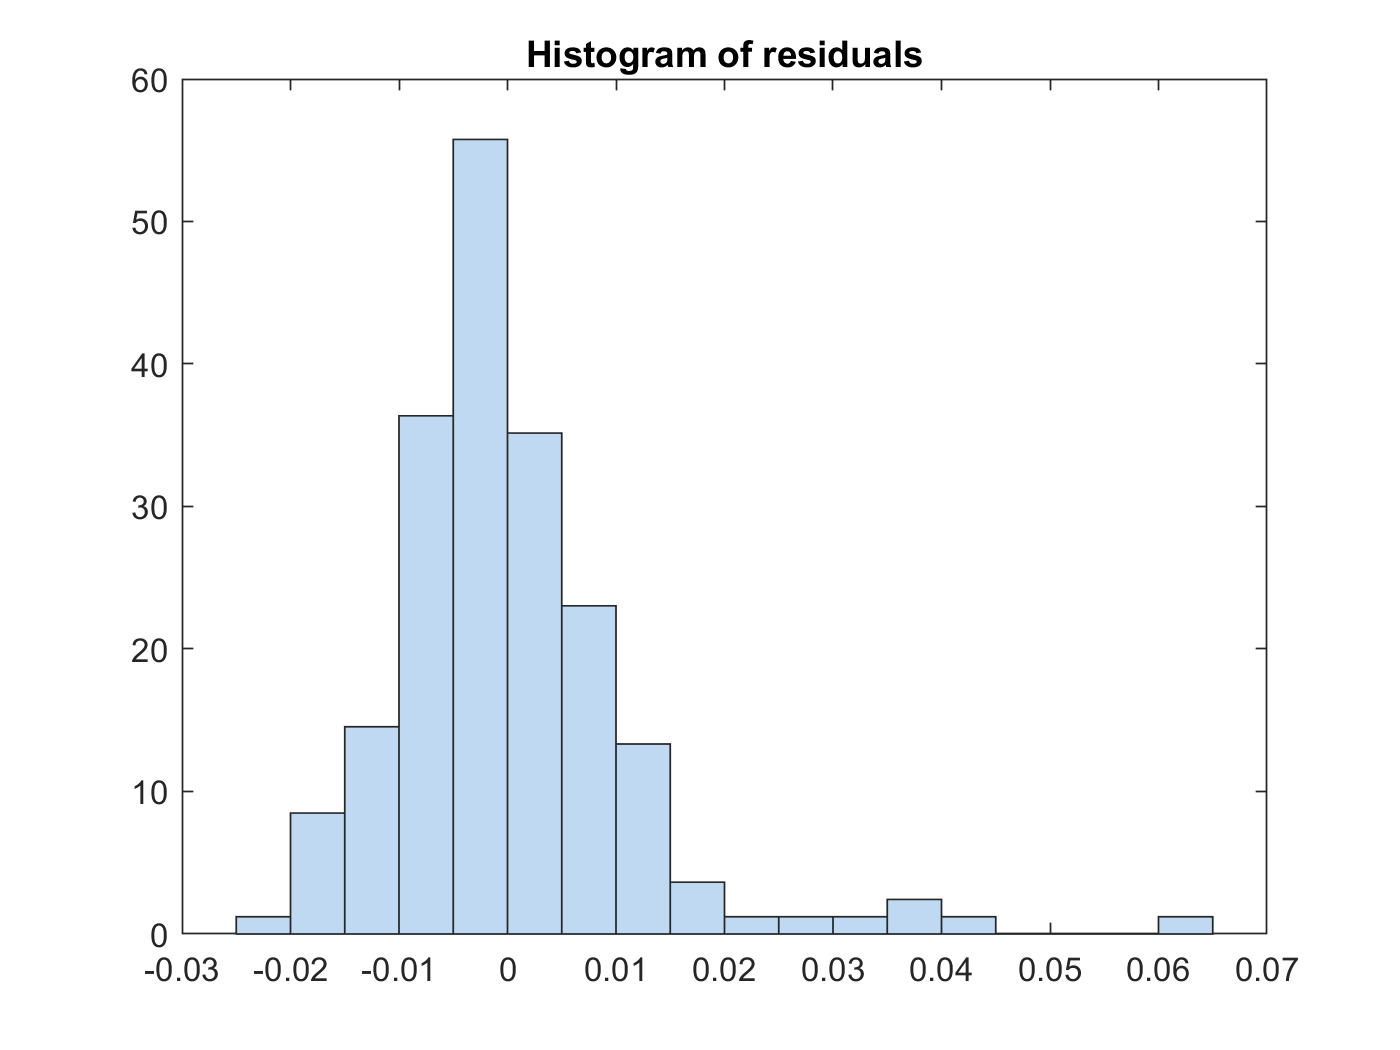

plotResiduals(mdl1)

모델링된 선형회귀식을 가지고 원래 데이타와 예측한 데이타를 비교하자

4.09585292607480	0.227155110205607	18.0310842330048	7.46164930980593e-41

-0.0952839654207921	0.00835224901979087	-11.4081806223706	1.35336543592271e-22

0.000196894463615833	1.30246355211347e-05	15.1170804969044	5.83185913112480e-33

-82.6228614134608	13.4185717416945	-6.15735139357142	5.43873148600241e-09


lm1 = fitlm(tbl,'linear')

lm1 = Linear regression model:
    cap ~ 1 + maxTimeDelta + maxTemp + ohm

Estimated Coefficients:
                          Estimate                   SE                   tStat                 pValue       
                    ____________________    ____________________    _________________    ____________________

    (Intercept)          4.0958529260748       0.227155110205607     18.0310842330048    7.46164930980593e-41
    maxTimeDelta    0.000196894463615833    1.30246355211347e-05     15.1170804969044     5.8318591311248e-33
    maxTemp          -0.0952839654207921     0.00835224901979087    -11.4081806223706    1.35336543592271e-22
    ohm                -82.6228614134608        13.4185717416945    -6.15735139357142    5.43873148600241e-09


Number of observations: 169, Error

lm2 = fitlm(tbl,'interactions')

lm2 = Linear regression model:
    cap ~ 1 + maxTimeDelta*maxTemp + maxTimeDelta*ohm + maxTemp*ohm

Estimated Coefficients:
                                  Estimate                   SE                   tStat                 pValue       
                            ____________________    ____________________    _________________    ____________________

    (Intercept)                 9.75739614932156       0.772069036440129     12.6379840257695    6.47244632753827e-26
    maxTimeDelta            -0.00168895152367066    5.57281390361562e-05    -30.3069787163515    1.19675893607186e-68
    maxTemp                   -0.254732707844396      0.0280777478217222    -9.07240528912094    3.76165569810085e-16
    ohm                         -1319.3521822802        240.696300788812    -5.48

lm3 = fitlm(tbl,'purequadratic')

lm3 = Linear regression model:
    cap ~ 1 + maxTimeDelta + maxTemp + ohm + maxTimeDelta^2 + maxTemp^2 + ohm^2

Estimated Coefficients:
                            Estimate                    SE                   tStat                 pValue       
                      _____________________    ____________________    _________________    ____________________

    (Intercept)            14.8676837737742        3.35643415936875     4.42960685889647    1.73088364066561e-05
    maxTimeDelta      -0.000155064598707851    0.000110535421276633    -1.40284984593107       0.162575215343899
    maxTemp              -0.888494371523491       0.232470551337521    -3.82196526145584    0.000188422971679479
    ohm                   -32.5428256654615        13.4146943071274    -2.42590885192002      

lm4 = fitlm(tbl,'quadratic')

lm4 = Linear regression model:
    cap ~ 1 + maxTimeDelta*maxTemp + maxTimeDelta*ohm + maxTemp*ohm + maxTimeDelta^2 + maxTemp^2 + ohm^2

Estimated Coefficients:
                                  Estimate                    SE                   tStat                 pValue       
                            _____________________    ____________________    _________________    ____________________

    (Intercept)                  8.88435830109125       0.933279949157315     9.51949981258377    2.77467700800025e-17
    maxTimeDelta            -0.000737272953253913    0.000106600482432446    -6.91622529683328    1.06917705168941e-10
    maxTemp                    -0.460363673805798      0.0716222814265303    -6.42766000519037    1.44017190499225e-09
    ohm                          365.99

%lm5 = fitlm(tbl,'polyi13')

testend =1;